disp('linear regression for groth model ');

linear regression for groth model 


% groth model 
% y= ax / b+x
x = [2.5 3.5 5 6 7.5 10] ; 
y = [5 3.4 2 1.6 1.2 0.8];

% (1/y) = (b/a)(1/x) + (1/a)
% Y = A X + B
%take the log for the y vector
X = 1./x ;
Y = 1./y  ;

% ∑ Y = A ∑ X + n B
% ∑ YX = A ∑ X^2 + B ∑ X

% get variable values

n=length(x)     ;  % n  
sX = sum(X)     ; % ∑ X
sY = sum(Y)     ; % ∑ Y
sXY = sum(X.*Y) ; % ∑ YX
sX2 = sum(X.^2) ; % ∑ X^2

% ∑ Y = a ∑ X + n B
% ∑ YX = a ∑ X^2 + B ∑ X

% we split this two equation into two matrices

Rightcoef = [sX n  ; sX2 sX ] ;  
Leftcoef = [sY ; sXY] ; 
%solve as matrices
%think of it as 
%Leftcoef = Rightcoef  * sol
sol = Rightcoef \ Leftcoef ;  % as same as 'sol  = Rightcoef^-1 * Leftcoef' but the backslash expression is more effcint for more info : https://www.mathworks.com/help/matlab/ref/mldivide.html

A= sol(1) ;    %A       
B = sol(2) ;   %B
a = 1/B  ;      %a 
b= A*a    ;     %b 

%calc R^2
yav = mean(Y) ;
st = sum( (Y-yav).^2 )  ;
sr = sum((Y-B-A*X).^2) ;
r2=(st-sr)/st ;


disp("a = "+a) ;

a = 0.78496


disp("b = "+b) ;

b = -2.4062


disp("r^2 = "+r2) ;

r^2 = 0.78388


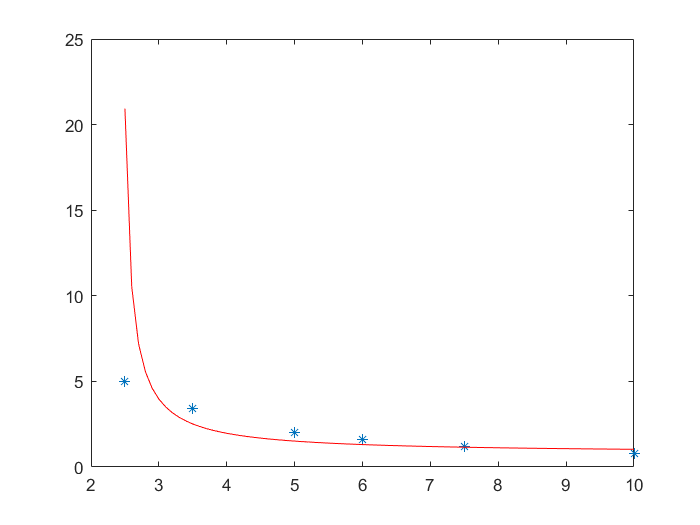


x1 = min(x):0.1:max(x) ;
%y= ax / b+X
y1 = (a*x1) ./ (b+x1) ;

plot(x,y ,'*' , x1 ,y1 ,'r-')